% clear variables;
load("result.mat");
workingMode = 2;
fittingType = 'DFT';


%% parameters Setting
% Start clock
initClock = clock;
initialHoppingParameterDataBase = [-2.430432, -0.040101, 0.097522, -0.070591, 0.0176250, -0.027414, 0.0046590, 0.001030, -0.010559, 0.000786, ...
    0.006749, -0.009858, 0.002722, -0.001447, 0.005350, -0.004718, 0.000434, 0.000423, 0.002563, 0.001689];
initialHoppingParameter = initialHoppingParameterDataBase(1: fittingNeighbourOrder);
%% Initialize fitting function (DO NOT EDIT THIS SECTION)
% Lattice Construction
a1 = [3.3291   -0.0000    0.0000];
a2 = [-1.6645    2.8831   -0.0000];
a3 = [0.0000   -0.0000   23.1180];
% Hopping Matrix & Hopping Parameter Construction
hoppingMatrix{1} = [0, 0, 0];
hoppingMatrix{2} = [-1, 0, 0; -1, -1, 0; 0, 1, 0; 0, -1, 0; 1, 1, 0; 1, 0, 0];
hoppingMatrix{3} = [-2, -1, 0; -1, 1, 0; -1, -2, 0; 1, 2, 0; 1, -1, 0; 2, 1, 0];
hoppingMatrix{4} = [-2, 0, 0; -2, -2, 0; 0, 2, 0; 0, -2, 0; 2, 2, 0; 2, 0, 0];
hoppingMatrix{5} = [-3,-1,0;-3,-2,0;-2,1,0;-2,-3,0;-1,2,0;-1,-3,0;1,3,0;1,-2,0;2,3,0;2,-1,0;3,2,0;3,1,0];
hoppingMatrix{6} = [-3,0,0;-3,-3,0;0,3,0;0,-3,0;3,3,0;3,0,0];
hoppingMatrix{7} = [-4,-2,0;-2,2,0;-2,-4,0;2,4,0;2,-2,0;4,2,0];
hoppingMatrix{8} = [-4,-1,0;-4,-3,0;-3,1,0;-3,-4,0;-1,3,0;-1,-4,0;1,4,0;1,-3,0;3,4,0;3,-1,0;4,3,0;4,1,0];
hoppingMatrix{9} = [-4,0,0;-4,-4,0;0,4,0;0,-4,0;4,4,0;4,0,0];
hoppingMatrix{10}= [-5,-2,0;-5,-3,0;-3,2,0;-3,-5,0;-2,3,0;-2,-5,0;2,5,0;2,-3,0;3,5,0;3,-2,0;5,3,0;5,2,0];
hoppingMatrix{11}= [-5,-1,0;-5,-4,0;-4,1,0;-4,-5,0;-1,4,0;-1,-5,0;1,5,0;1,-4,0;4,5,0;4,-1,0;5,4,0;5,1,0];
hoppingMatrix{12}=[-5,0,0;-5,-5,0;0,5,0;0,-5,0;5,5,0;5,0,0];
hoppingMatrix{13}=[-6,-3,0;-3,3,0;-3,-6,0;3,6,0;3,-3,0;6,3,0];
hoppingMatrix{14}=[-6,-2,0;-6,-4,0;-4,2,0;-4,-6,0;-2,4,0;-2,-6,0;2,6,0;2,-4,0;4,6,0;4,-2,0;6,4,0;6,2,0];
hoppingMatrix{15}=[-6,-1,0;-6,-5,0;-5,1,0;-5,-6,0;-1,5,0;-1,-6,0;1,6,0;1,-5,0;5,6,0;5,-1,0;6,5,0;6,1,0];
hoppingMatrix{16}=[-6,0,0;-6,-6,0;0,6,0;0,-6,0;6,6,0;6,0,0];
hoppingMatrix{17}=[-7,-3,0;-7,-4,0;-4,3,0;-4,-7,0;-3,4,0;-3,-7,0;3,7,0;3,-4,0;4,7,0;4,-3,0;7,4,0;7,3,0];
hoppingMatrix{18}=[-7,-2,0;-7,-5,0;-5,2,0;-5,-7,0;-2,5,0;-2,-7,0;2,7,0;2,-5,0;5,7,0;5,-2,0;7,5,0;7,2,0];
hoppingMatrix{19}=[-7,-1,0;-7,-6,0;-6,1,0;-6,-7,0;-1,6,0;-1,-7,0;1,7,0;1,-6,0;6,7,0;6,-1,0;7,6,0;7,1,0];
hoppingMatrix{20}=[-8,-4,0;-4,4,0;-4,-8,0;4,8,0;4,-4,0;8,4,0];
hoppingParameter{1} = -2.430432;
hoppingParameter{2} = -0.0401010000000000;
hoppingParameter{3} = 0.0975220000000000;
hoppingParameter{4} = -0.0705910000000000;
hoppingParameter{5} = 0.0176250000000000;
hoppingParameter{6} = -0.0274140000000000;
hoppingParameter{7} = 0.00465900000000000;
hoppingParameter{8} = 0.00103000000000000;
hoppingParameter{9} = -0.0105590000000000;
hoppingParameter{10}= 0.000786000000000000;
hoppingParameter{11}= 0.00674900000000000;
hoppingParameter{12}= -0.00985800000000000;
hoppingParameter{13}= 0.00272200000000000;
hoppingParameter{14}= -0.00144700000000000;
hoppingParameter{15}= 0.00535000000000000;
hoppingParameter{16}= -0.00471800000000000;
hoppingParameter{17}= 0.000434000000000000;
hoppingParameter{18}= 0.000423000000000000;
hoppingParameter{19}= 0.00256300000000000;
hoppingParameter{20}= 0.00168900000000000;

% Lattice data Processing
transMatA = [a1;a2;a3];
V = dot(a1, cross(a2, a3));
b1 = 2*pi*cross(a2,a3)/V;
b2 = 2*pi*cross(a3,a1)/V;
b3 = 2*pi*cross(a1,a2)/V;
transMatB = [b1;b2;b3];

if workingMode == 2
    % Generates K-Path (Path Working Mode)
    kpoints{1} = [0 0 0]* transMatB;
    kpoints{2} = [0 0.5 0]* transMatB;
    kpoints{3} = [-0.3333 0.6667 0.0]* transMatB;
    kpoints{4} = [0 0 0]* transMatB;
    Ntot = 50;
    for loopIndex = 1: length(kpoints) - 1
        kPointsMesh(Ntot*(loopIndex - 1) + 1: Ntot* loopIndex, 1: 3) = [linspace(kpoints{loopIndex}(1), kpoints{loopIndex + 1}(1), Ntot)', linspace(kpoints{loopIndex}(2), kpoints{loopIndex + 1}(2), Ntot)', ...
            linspace(kpoints{loopIndex}(3), kpoints{loopIndex + 1}(3), Ntot)'];
    end
    numIdx = Ntot: Ntot:(length(kpoints) - 2)*Ntot;
    kPointsMesh(numIdx, :) = [];
    kPathDistance = 0;
    kPointsMesh(1, 4) = 0;
    for loopIndex = 2: length(kPointsMesh)
        sqrtPart(1) = (kPointsMesh(loopIndex, 1) - kPointsMesh(loopIndex - 1, 1));
        sqrtPart(2) = (kPointsMesh(loopIndex, 2) - kPointsMesh(loopIndex - 1, 2));
        sqrtPart(3) = (kPointsMesh(loopIndex, 3) - kPointsMesh(loopIndex - 1, 3));
        kPathDistance = kPathDistance + sqrt(sqrtPart(1)^2 + sqrtPart(2)^2 + sqrtPart(3)^2 );
        kPointsMesh(loopIndex, 4) = kPathDistance;
    end
    kPointsMesh = kPointsMesh';
    switch fittingType
        case 'WannierFit'
            load('wannier90_band.dat');
            % Interpolante the wannier fitting results for calculating difference.
            interpGrid = griddedInterpolant(wannier90_band(:, 1), wannier90_band(:, 2), 'linear');
            targetHkin = interpGrid(kPointsMesh(4, :)) - fermiLevel;
        case 'DFT'
            load('savedFigureData.mat');
            targetHkin = exportData.bandStructure.energy{12};
    end
    
else
    % OR import K-mesh (Plane Working Mode)
    load('savedFigureData.mat');
    selectionIndex = ~isnan(exportData.bandStructure_3D.bandeigenvalueSelected);
    kPointsMesh = exportData.hubbardModel.kpointsRecipMeshSelected(1:3, selectionIndex);
    targetHkin = exportData.hubbardModel.bandeigenvalueSelected(selectionIndex);
end

diff = cell(1, length(x));
for fittingOrder = 1: 20
    updatedHoppingParameter = num2cell(x{fittingOrder, 2});
    calcHkin = zeros(1, length(kPointsMesh));
    initHkin = zeros(1, length(kPointsMesh));
    % Extra modification for parallel calc, avoiding extra communication
    % overhead
    kPointsMeshCalc = kPointsMesh(1:3, :)';
    kPointsMeshInit = kPointsMesh(1:3, :)';
    parfor loopIndex = 1:length(kPointsMesh)
        calcHkin(loopIndex) = calculateKineticHamiltonian(transMatA, kPointsMeshCalc(loopIndex, :), updatedHoppingParameter, hoppingMatrix);
        initHkin(loopIndex) = calculateKineticHamiltonian(transMatA, kPointsMeshInit(loopIndex, :), hoppingParameter, hoppingMatrix);
    end
    
    switch workingMode
        case 1
            diff{fittingOrder} = calculateDifference(2, kPointsMesh(1, :)', fermiLevel ,calcHkin, targetHkin);
            %             figure();
            %             scatter3(kPointsMesh(1, :), kPointsMesh(2, :), real(calcHkin) - exportData.fermiLevel, 1);
            %             figure();
            %             scatter3(kPointsMesh(1, :), kPointsMesh(2, :), real(diff), 1);
        case 2
            diff{fittingOrder} = calculateDifference(2, kPointsMesh(3, :)', fermiLevel ,calcHkin, targetHkin);
            %             figure();
            %             plot(kPointsMesh(4, :), real(calcHkin) - fermiLevel, 'b');
            %             hold on;
            %             plot(kPointsMesh(4, :), real(targetHkin), 'r');
            %             plot(kPointsMesh(4, :), real(initHkin) - fermiLevel, 'k--');
            %             legend(["Calculate", "Target", "Initial"]);
            %             hold off;
            %             figure();
            %             plot(kPointsMesh(4, :), diff);
    end
    FinClock = clock;
    timeDuration = etime(FinClock, initClock);
end
disp(diff);

  列 1 至 5

    [1.7787]    [-1.3229]    [-1.4698]    [1.8776]    [-0.8511]

  列 6 至 10

    [1.1965]    [-1.4101]    [-1.2426]    [0.6824]    [-1.0500]

  列 11 至 15

    [-1.0252]    [-1.1629]    [1.0152]    [-2.0645]    [1.5403]

  列 16 至 20

    [-0.8563]    [-1.7648]    [-1.0389]    [0.6860]    [-1.8683]



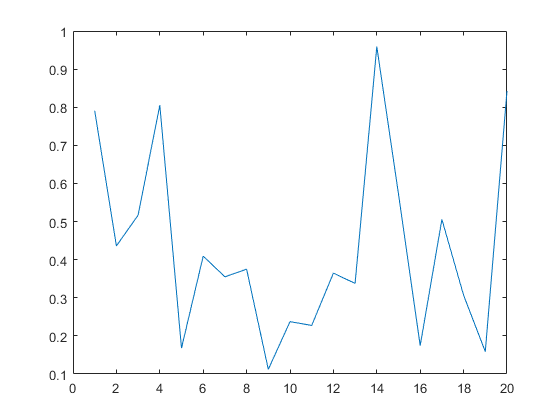

plot(1: length(diff), abs([diff{:}]));

[energy, DOS] = calculateDOS(targetHkin, 0.08, [-44.334 27.380], 2000);
plot(energy, DOS);
hold on
plot(exportData.totalDOS.energy, exportData.totalDOS.dos);
hold off

xlim([-4 4])
ylim([0.00 9.15])

clear variables
tic
% func = @(x)(x.^2 - 10 * cos(2*pi()*x) + 10);
func = @(x)(1/4000*x.^2 - cos(x) + 1);
rng(0);
init = -60 + 120.*rand(1, 10000);
fminuncOptions = optimoptions('fminunc', "Algorithm","quasi-Newton", "MaxIterations", 10000,...
    "Display","iter",'FunctionTolerance',1e-9,...
    "MaxFunctionEvaluations", 4000, "UseParallel",true, "FiniteDifferenceType", 'central');
parfor numIdx = 1: 10000
    [x(numIdx),fval(numIdx),exitflag(numIdx),output(numIdx),~,~] = fminunc(func, init(numIdx), fminuncOptions);
end

                                                        First-order 
 Iteration  Func-count       f(x)        Step-size       optimality
     0           3        0.0585242                         0.308
     1           6       0.00987765              1         0.0051  
     2           9       0.00986468              1       8.82e-05  
     3          12       0.00986467              1       1.08e-09  

Computing finite-difference Hessian using objective function.

Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

                                                        First-order 
 Iteration  Func-count       f(x)        Step-size       optimality
     0           3           1.7179                         0.717
     1           9        0.0414816        3.15853         0.0636  
     2          15        0.0394587       0.288291       7.74e-05  
     3          18        0.0394587              1       6.

length(find(abs(x) < 0.01))

ans = 1327

toc

Elapsed time is 53.646956 seconds.


clear variables;
fun = @(x) x.^2 + 4*sin(5*x);
rng default % For reproducibility
opts = optimoptions(@fmincon,'Algorithm','sqp');
problem = createOptimProblem('fmincon','objective',...
    fun,'x0',3,'lb',-5,'ub',5,'options',opts);
gs = GlobalSearch;
[x,f] = run(gs,problem)


GlobalSearch stopped because it analyzed all the trial points.

All 23 local solver runs converged with a positive local solver exit flag.


x = -0.3080

f = -3.9032

function Hkin = calculateKineticHamiltonian(transMat, kpointsRecip, hoppingParameter, hoppingMatrixProcessed)
Hkin = 0;
for hoppingOrder = 1: length(hoppingParameter)
    sum = 0;
    hoppingLength = length(hoppingMatrixProcessed{hoppingOrder}(:, 1));
    a1part = cell(1, hoppingLength);
    a2part = cell(1, hoppingLength);
    a3part = cell(1, hoppingLength);
    dotpart = zeros(1, hoppingLength);
    for NumIdx = 1: hoppingLength
        a1part{NumIdx} = hoppingMatrixProcessed{hoppingOrder}(NumIdx, 1).*transMat(1, :);
        a2part{NumIdx} = hoppingMatrixProcessed{hoppingOrder}(NumIdx, 2).*transMat(2, :);
        a3part{NumIdx} = hoppingMatrixProcessed{hoppingOrder}(NumIdx, 3).*transMat(3, :);
        dotpart(NumIdx) = dot(kpointsRecip, a1part{NumIdx} + a2part{NumIdx} + a3part{NumIdx});
        sum = sum + exp(1i*dotpart(NumIdx));
    end
    Hkin = Hkin + hoppingParameter{hoppingOrder}*sum;
end
end

% This calculateDifference function can be customized depending on your
% fitting error method.
function diff = calculateDifference(workingMode, kpointsRecip, fermiLevel ,calcHkin, targetHkin)
difference = zeros(1, length(kpointsRecip));
for LoopIndex = 1: length(kpointsRecip)
    difference(LoopIndex) = calcHkin(LoopIndex) - fermiLevel - targetHkin(LoopIndex);
end

switch workingMode
    case 1
        diff = real(difference);
    case 2
        [~, maxIdx] = max(abs(difference));
        diff = real(difference(maxIdx));
    case 3
        diff = mean(real(difference));
    case 4
        diff = var(real(difference));
end
end

function fittingDifference = calculateTargetFunction(workingMode, transMatA, kPointsMesh, hoppingParameter,...
    hoppingMatrix, fermiLevel, targetHkin, calcDiffMethod)

hoppingParameterCell = num2cell(hoppingParameter);
Hkin = zeros(1, length(kPointsMesh));
for LoopIndex = 1:length(kPointsMesh)
    Hkin(LoopIndex) = calculateKineticHamiltonian(transMatA, kPointsMesh(1:3, LoopIndex)', hoppingParameterCell, hoppingMatrix);
end
switch workingMode
    case 1
        Diff = calculateDifference(calcDiffMethod, kPointsMesh(1, :)', fermiLevel, Hkin, targetHkin);
        fittingDifference = abs(Diff);
    case 2
        Diff = calculateDifference(calcDiffMethod, kPointsMesh(4, :)', fermiLevel, Hkin, targetHkin);
        fittingDifference = abs(Diff);
end
end

function [energy, DOS] = calculateDOS(Hkin, resolution, energyRange, insertNumber)

% Hkin:         Matrix that stores the band working mode calculated kinetic
%               energy
%               Type:       Complex, Matrix, Necessary
%               Dimension:  1 x N
%


% resolution:   Value that stores imaginary offset in calculating DOS
%               Type:       Double, Value, optional
%               Default:    1e-8

% energyRange:  Value that stores imaginary offset in calculating DOS
%               Type:       Double, Value, optional
%               Default:    [-4, 4] (eV)

% insertNumber: Value that stores total DOS calculate number
%               Type:       Int, Value, optional
%               Default:    400
if nargin == 0
    [energy, DOS] = nan(1, 2);
    return
elseif nargin == 1
    resolution = 0.01;
    energyRange = [-4, 4];
    insertNumber = 400;
elseif nargin == 2
    energyRange = [-4, 4];
    insertNumber = 400;
elseif nargin == 3
    insertNumber = 400;
end

omega = linspace(energyRange(1), energyRange(2), insertNumber);
GreenFunc = zeros(1, length(omega));
DOS = zeros(1, length(omega));
% $$ G(\omega) = \frac{1}{N_k} \sum_k \frac{1}{\omega - \varepsilon_k + i\Gamma}$$
% $$ -\frac{1}{\pi} Im G(\omega)$$
parfor omegaNumIdx = 1: length(omega)
    for kNumIdx = 1: length(Hkin)
        GreenFunc(omegaNumIdx) = GreenFunc(omegaNumIdx) + ...
            1/(omega(omegaNumIdx) - (Hkin(kNumIdx)) + 1i* resolution);
    end
    GreenFunc(omegaNumIdx) = GreenFunc(omegaNumIdx) ./ length(Hkin);
    DOS(omegaNumIdx) = -1/pi()*imag(GreenFunc(omegaNumIdx));
end
energy = omega;
end